## **Walkthrough on simulation datasets (take dataset 1 and 8 as examples)**

### Dataset 1

addpath('./Data')
load('dataset1.mat')

#### Run scAI

K = 3;
alpha = 1; lambda = 10000; gamma = 1; s = 0.25;
result = run_scAI(X1,X2,K,alpha,lambda,gamma,s);
result

result = 1×10 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


#### Select the best solution of scAI 

best_one = choose_best_performance(result);

The best seed is 1


#### Downstream analyses

1. Heatmap of cell loading matrix H

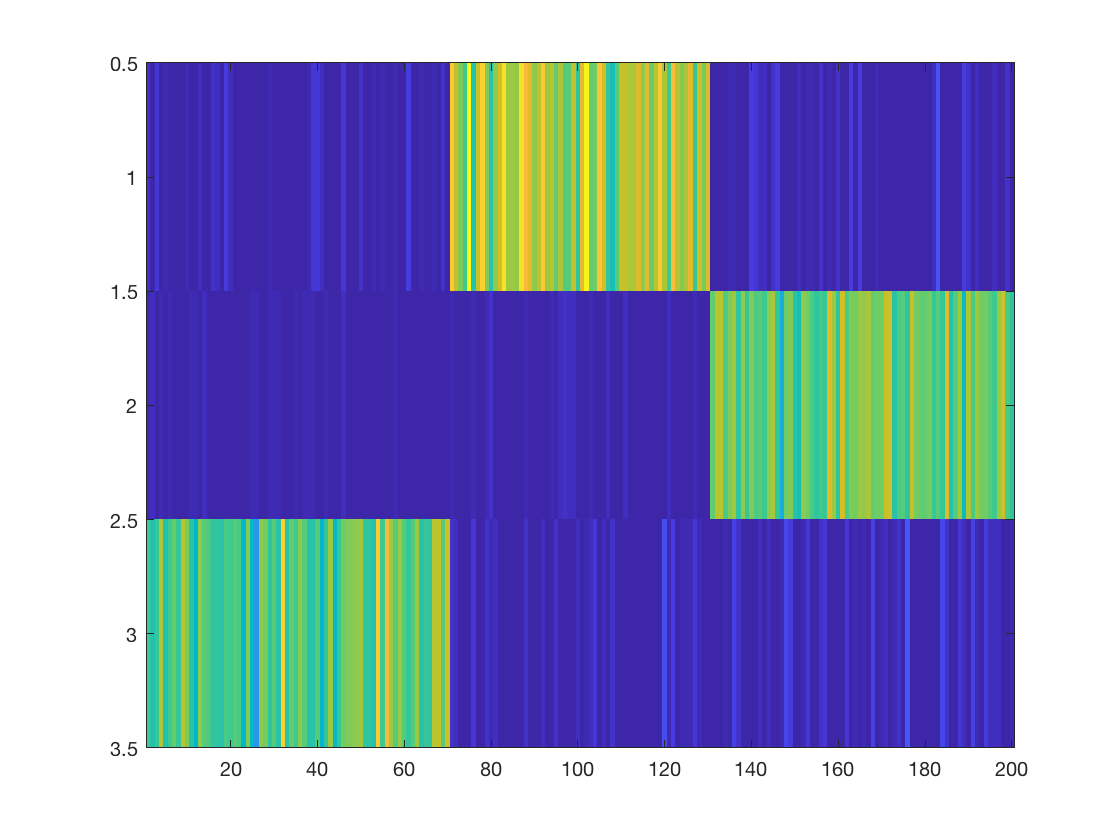

figure; imagesc(best_one.H)

2. Visualize the cells by performing t-SNE (UMAP) on the aggregated epigenomic data obtained by scAI

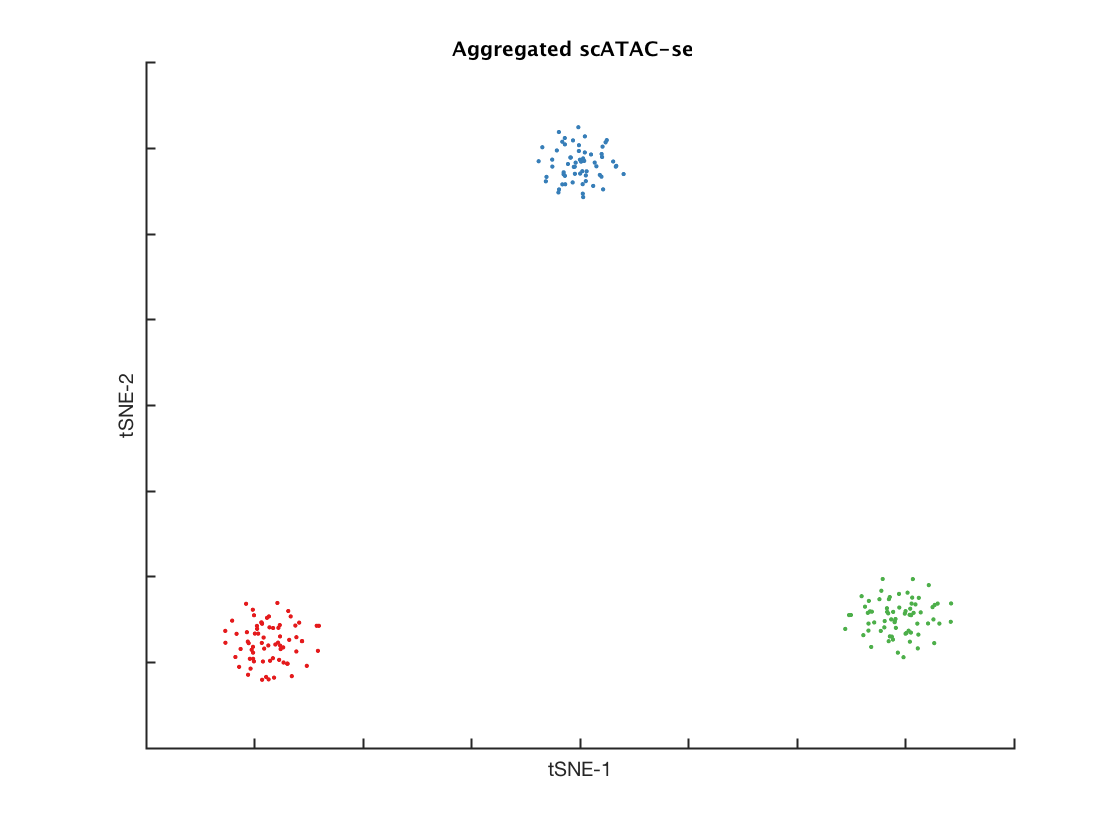

X2a = generate_aggregated_matrix(X2,best_one);
Cells = []; method = 'tSNE';
cell_coords = reducedDims(X2a,Cells,method);
title_name = 'Aggregated scATAC-seq';
clust = []; term = true_label; colors = [];
cellVisualizaiton(cell_coords,clust,term,colors,title_name,method);

### Dataset 8

addpath('./Data')
load('dataset8.mat')

#### Run scAI

K = 5;
alpha = 1; lambda = 10000; gamma = 1; s = 0.25;
result = run_scAI(X1,X2,K,alpha,lambda,gamma,s);
result

result = 1×10 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


#### Select the best solution of scAI 

best_one = choose_best_performance(result);

The best seed is 1


#### Downstream analyses

1. Heatmap of cell loading matrix H

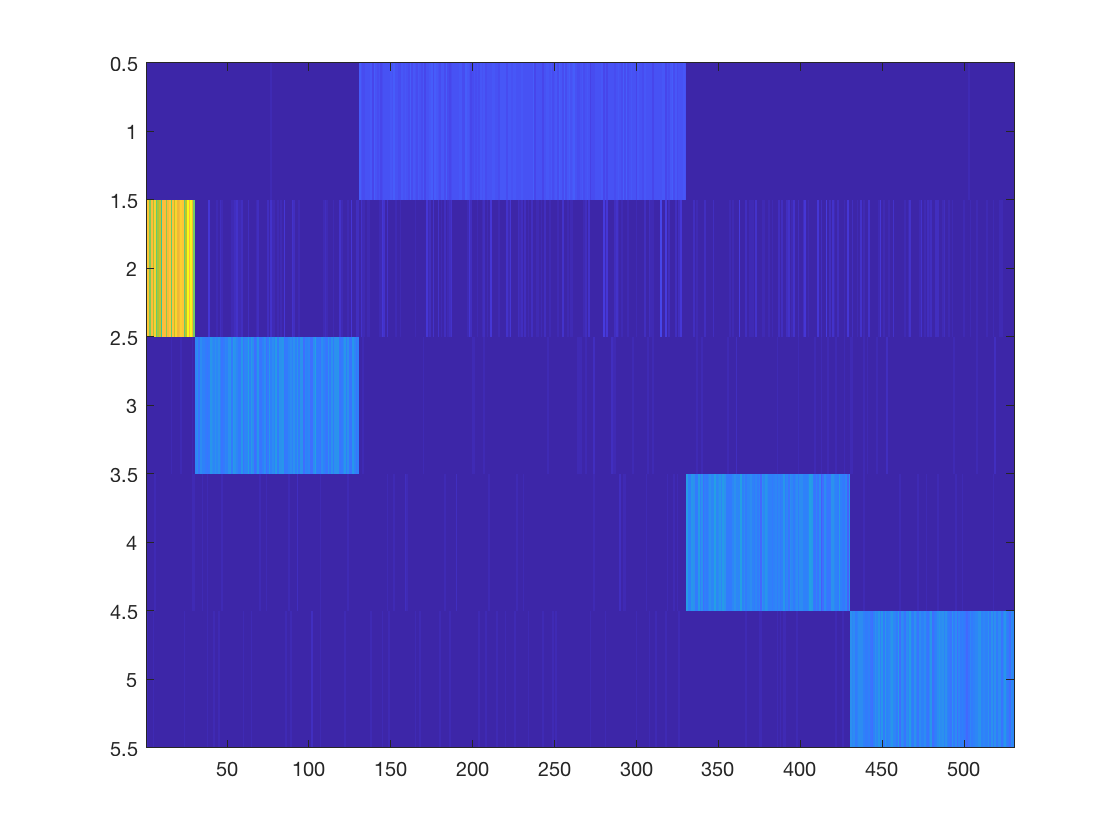

figure; imagesc(best_one.H)

2. Visualize the cells by performing t-SNE (UMAP) on the aggregated epigenomic data obtained by scAI

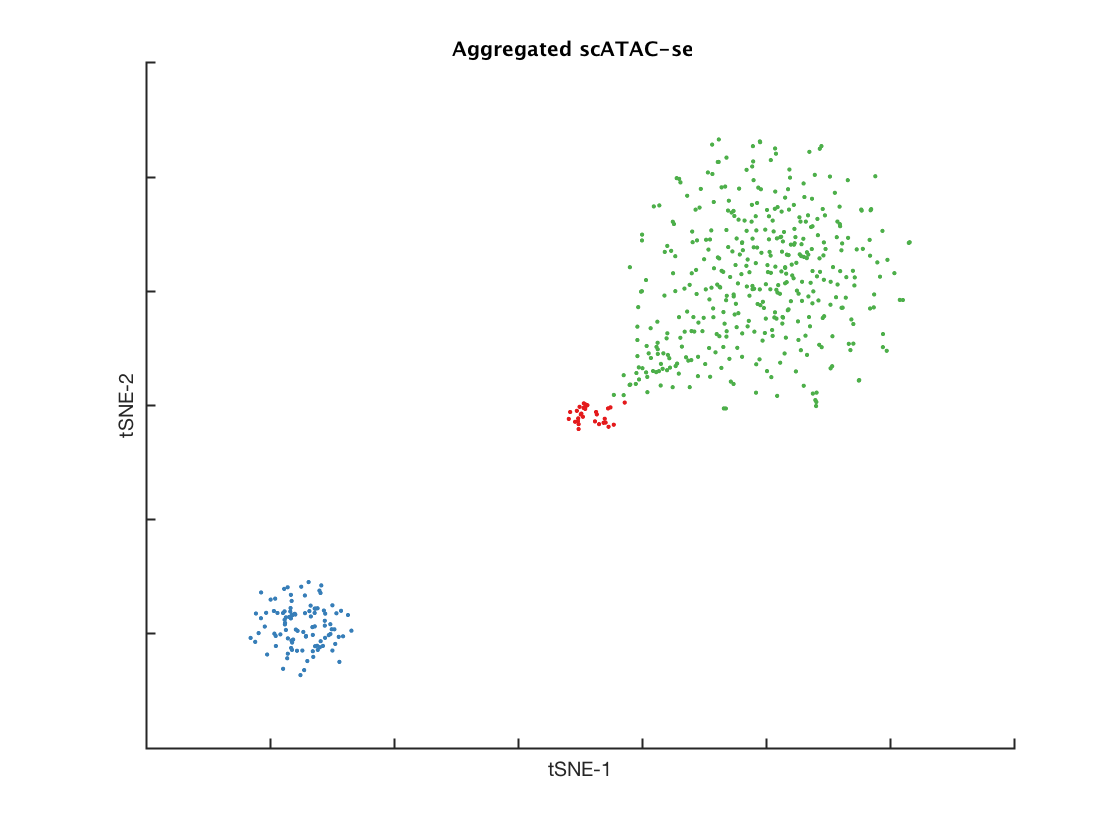

X2a = generate_aggregated_matrix(X2,best_one);
Cells = []; method = 'tSNE';
cell_coords = reducedDims(X2a,Cells,method);
title_name = 'Aggregated scATAC-seq';
clust = []; term = true_label2; colors = [];
cellVisualizaiton(cell_coords,clust,term,colors,title_name,method);